clear; close all; clc;

To draw a random variable Z from the inverse gamma distribution with mean $\mu$ and standard deviation $\sigma$,

mu = rand;
sigma = rand;


$$Z \sim \Gamma^{-1}(a,b)\\
\text{where } a = \bigg(\frac{\mu}{\sigma}\bigg)^2+2,\quad b = (a-1)\mu$$


a = (mu/sigma)^2+2;
b = (a-1)*mu;

This is equivalent to draw $Z^{-1}$ from the gamma distribution with the following parameters


$$Z^{-1} \sim \Gamma(a,b^{-1})\\
\text{where } a = \bigg(\frac{\mu}{\sigma}\bigg)^2+2,\quad b = (a-1)\mu$$


N = 2e3;
z = invgamrnd(mu,sigma,N,1);


$$p_{\Gamma^{-1}}(Z) = p_{\Gamma}(Z^{-1})Z^{-2}$$


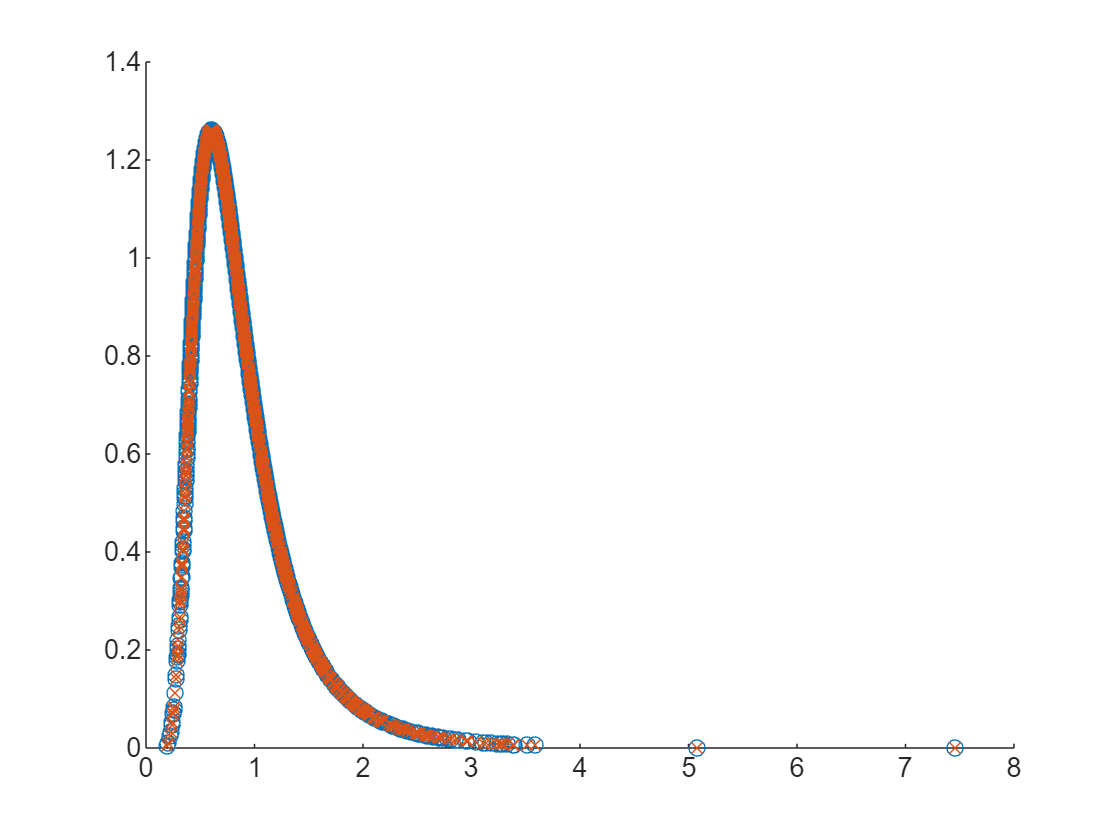

figure
hold on
plot(z,invgampdf(z,mu,sigma),'o')
plot(z,gampdf(1./z,a,1/b).*z.^(-2),'x');
hold off

[mu mean(z)]

ans =     0.9434    0.9316


[sigma std(z)]

ans =     0.5809    0.5349
